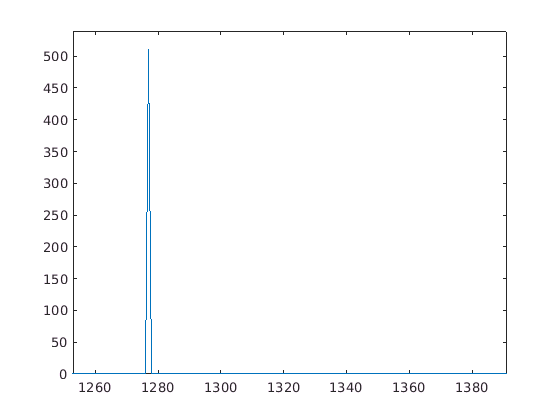

clear all; close all; clc;

sps = 4;
rho = 1;
span = 8;
c = lteZadoffChuSeq(1, 511);
cc = [c; c];
cprime = circshift(c, 256);
plot(abs(xcorr(cc, cprime)))

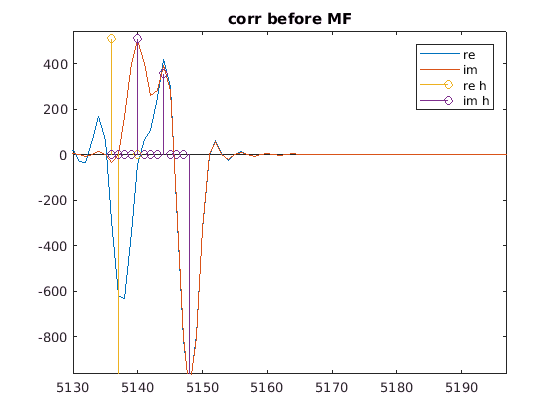



pulse_shaping = dsp.FIRInterpolator('InterpolationFactor', sps, 'Numerator', rcosdesign(rho, span, sps,'sqrt'));
g = pulse_shaping.impz;
s = pulse_shaping(cc) / max(g);
h = [1,]; h(sps/2) = -2; h(1*sps+1) = 1j; h(2*sps+1) = .7+.7j; h(3*sps+1) = -2-2j;
r = conv(s, h);
rn = awgn(r, 50, 'measured');
y = conv(rn, pulse_shaping.impz);
upsampling = dsp.FIRInterpolator('InterpolationFactor', sps, 'Numerator', [1,]);
cprime_up = upsampling(cprime);
%plot(abs(cprime_up));
rcorr = xcorr(rn, cprime_up);
ycorr = xcorr(y, cprime_up);
plot(real(rcorr)); hold on; plot(imag(rcorr)); stem(5136:5136+length(h)-1, length(cprime) * real(h)); stem(5136:5136+length(h)-1, length(cprime) * imag(h)); legend('re', 'im', 're h', 'im h'); title('corr before MF'); hold off;
xlim([5130 5197])
ylim([-964 544])

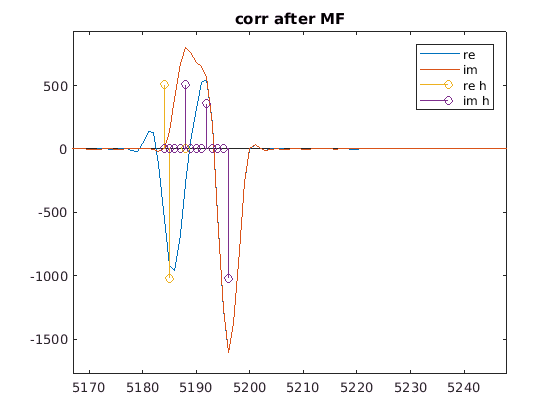



plot(real(ycorr)); hold on; plot(imag(ycorr)); stem(5184:5184+length(h)-1, length(cprime) * real(h)); stem(5184:5184+length(h)-1, length(cprime) * imag(h)); legend('re', 'im', 're h', 'im h'); title('corr after MF'); hold off;

xlim([5167 5248])
ylim([-1776 931])

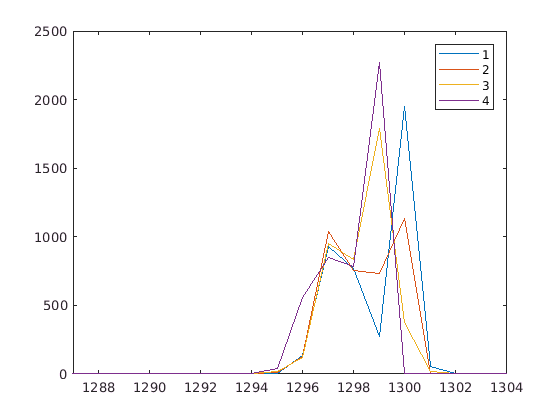

ycorr(length(ycorr) + sps - mod(length(ycorr), 4)) = 0;
ycorrpf = reshape(ycorr, sps, []);
plot(abs(ycorrpf')); legend('1', '2', '3', '4');

xlim([1287 1304])
ylim([0 2500])

sum_energy = sum(abs(ycorrpf(:, 1290:1304)).^2, 2)

sum_energy =    1.0e+06 *

    5.3525
    3.4934
    4.9569
    6.8160


[maxval, maxpfc] = max(sum_energy)

maxval = 6.8160e+06

maxpfc = 4